# Y-shape Laplacian program

Computes the eigenvalues and eigenfunctions of the Laplace operator on a dumbbell graph

## Set up the graph structure and coordinates of the problem

[source,target]=yShapeTemplate;
LVec=[3 1 1];
nX=round(50*LVec);
Phi = quantumGraph(source,target,LVec,'nxVec',nX);

## Set up coordinates on which to plot the solutions

Note that the user has to create the plotting function. Note further, you could also add this by adding the key-value pair 'PlotCoordinateFcn',@dumbbellPlotCoords to the above line of code Phi = quantumGraph(...

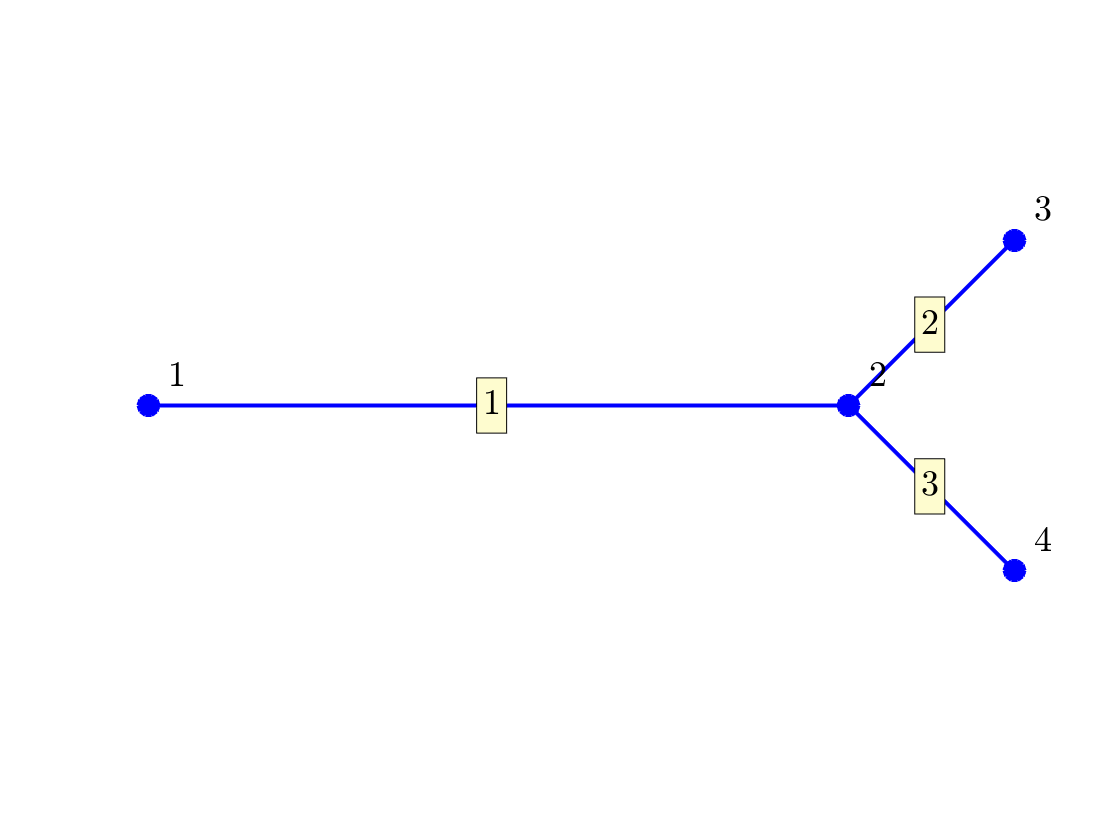

Phi.addPlotCoords(@yShapePlotCoords);
Phi.plot('layout')

## Construct the Laplacian and calculate its eigenvalues and eigenvectors

A little cleanup needed because the null eigenvalue is sometimes calculated as positive and sometimes as negative and this screws up the sorting.

[V,lambda]=eig(Phi);
[singles,doubles,~]=separateEigs(lambda); % No triple eigenvalue unless handle and hoops resonant
nToPlot=4;

## Plot the first few multiplicity-one eigenfunctions

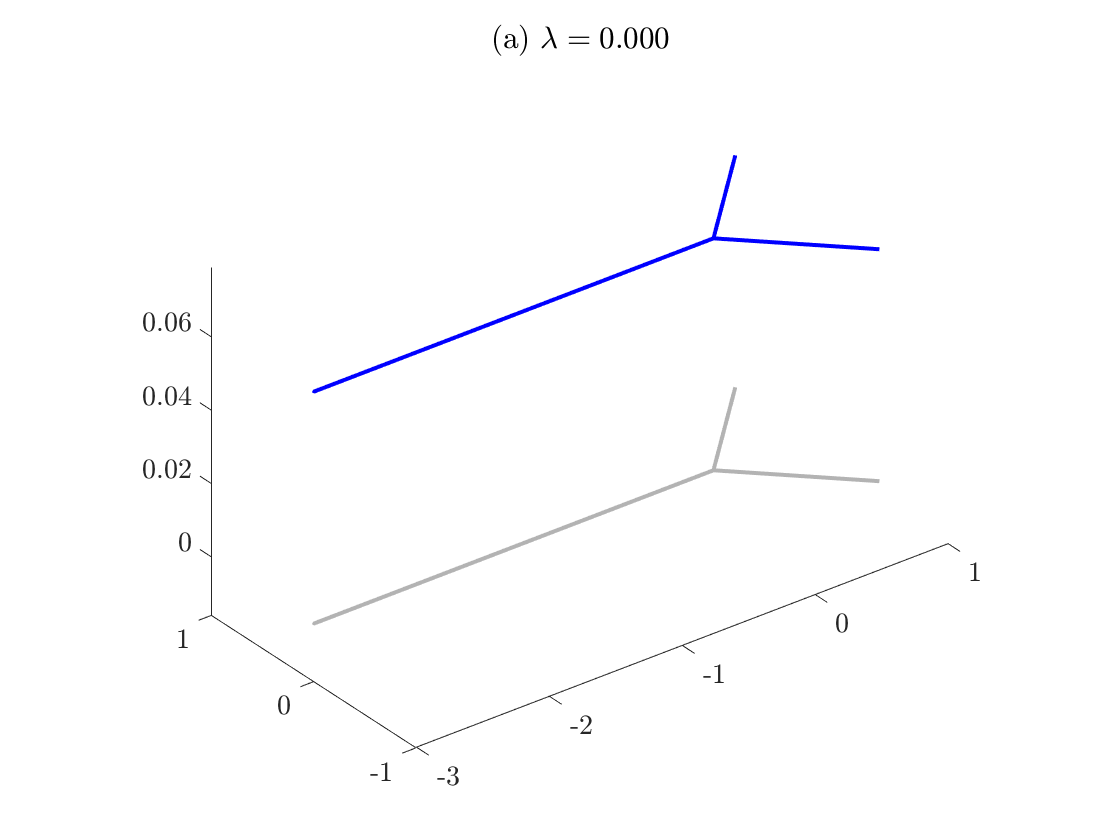

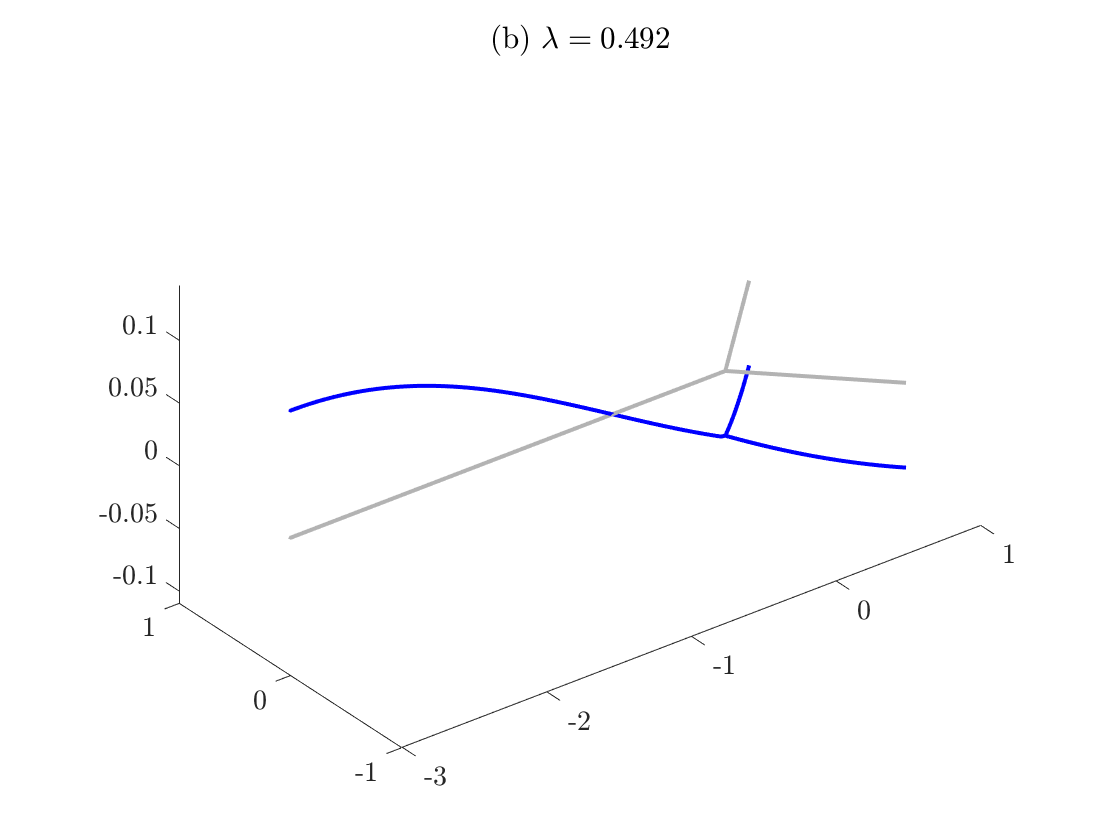

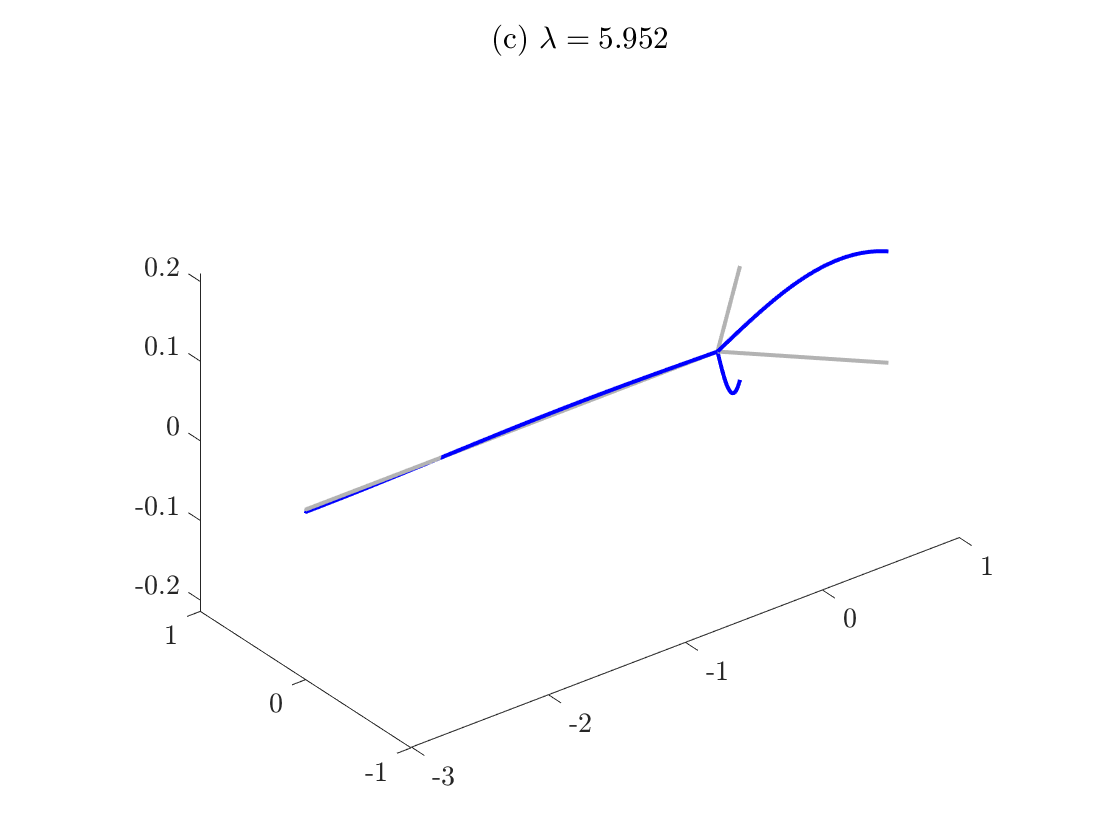

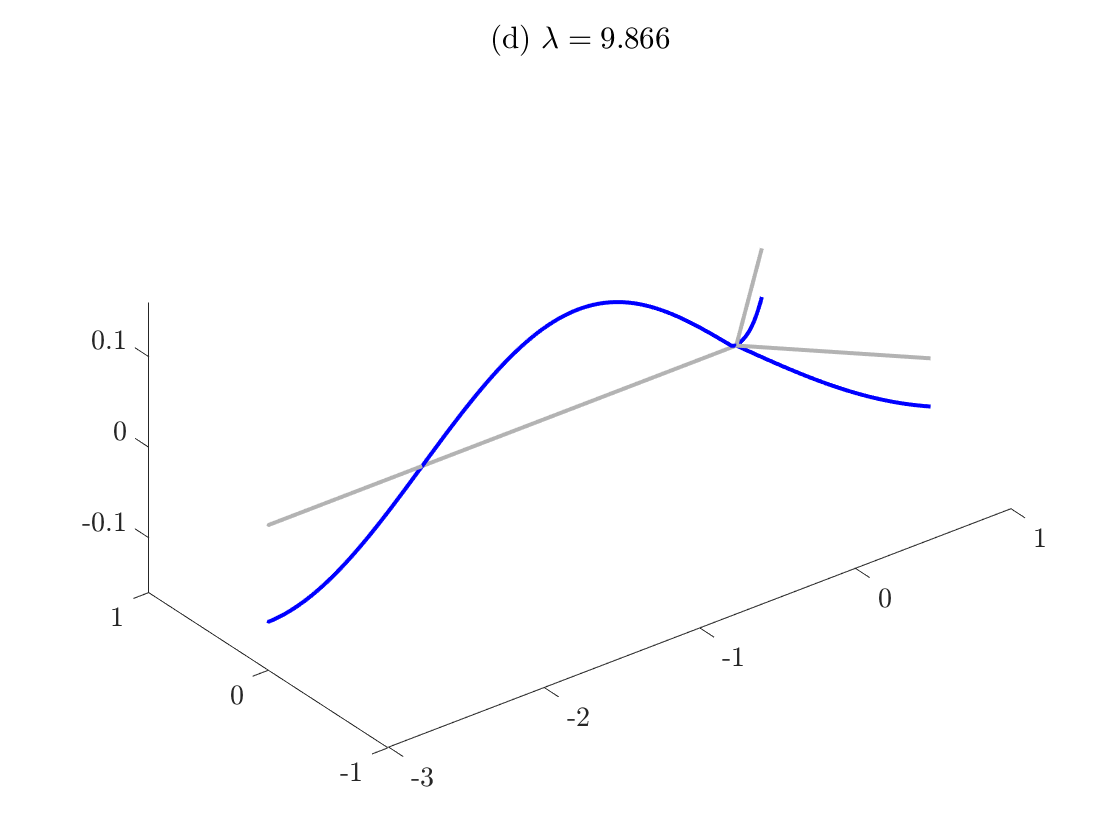

for k=1:nToPlot
    figure
    Phi.plot(V(:,single(k)))
    title(sprintf('(%s) $\\lambda = %0.3f$', letter(k),lambda(singles(k))));
end

## Plot the first few multiplicity-two eigenfunctions

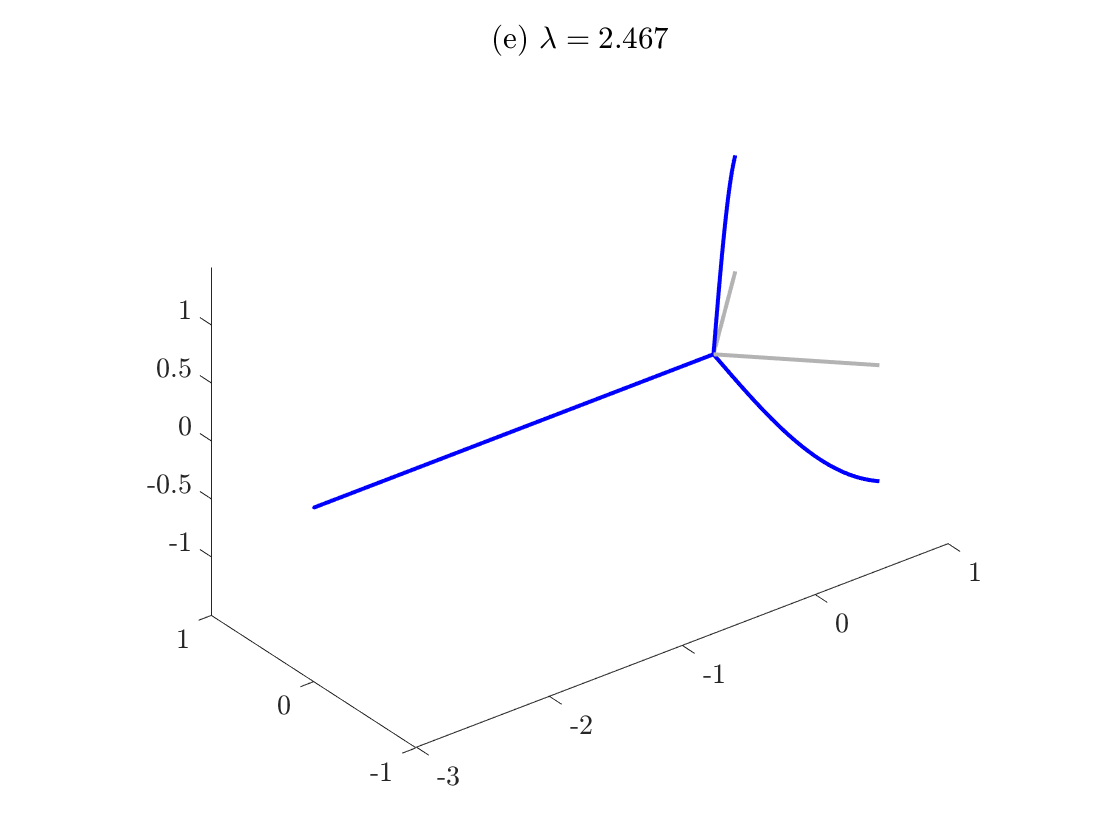

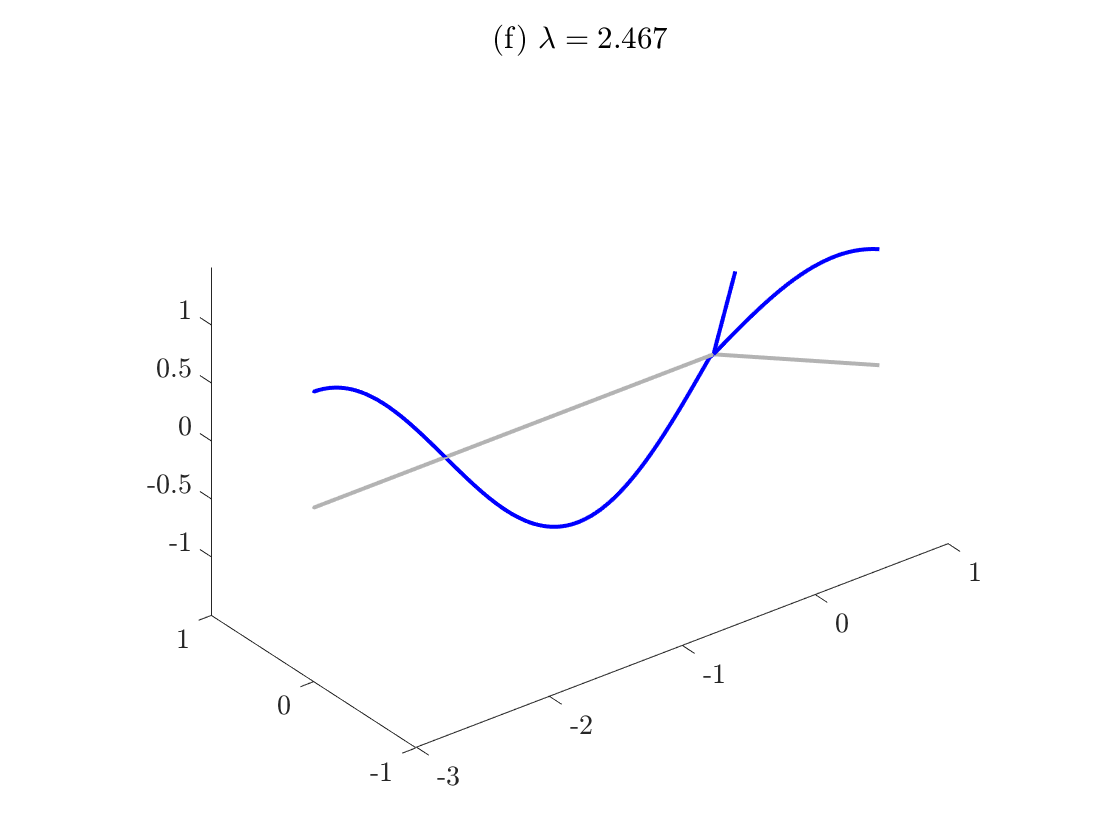

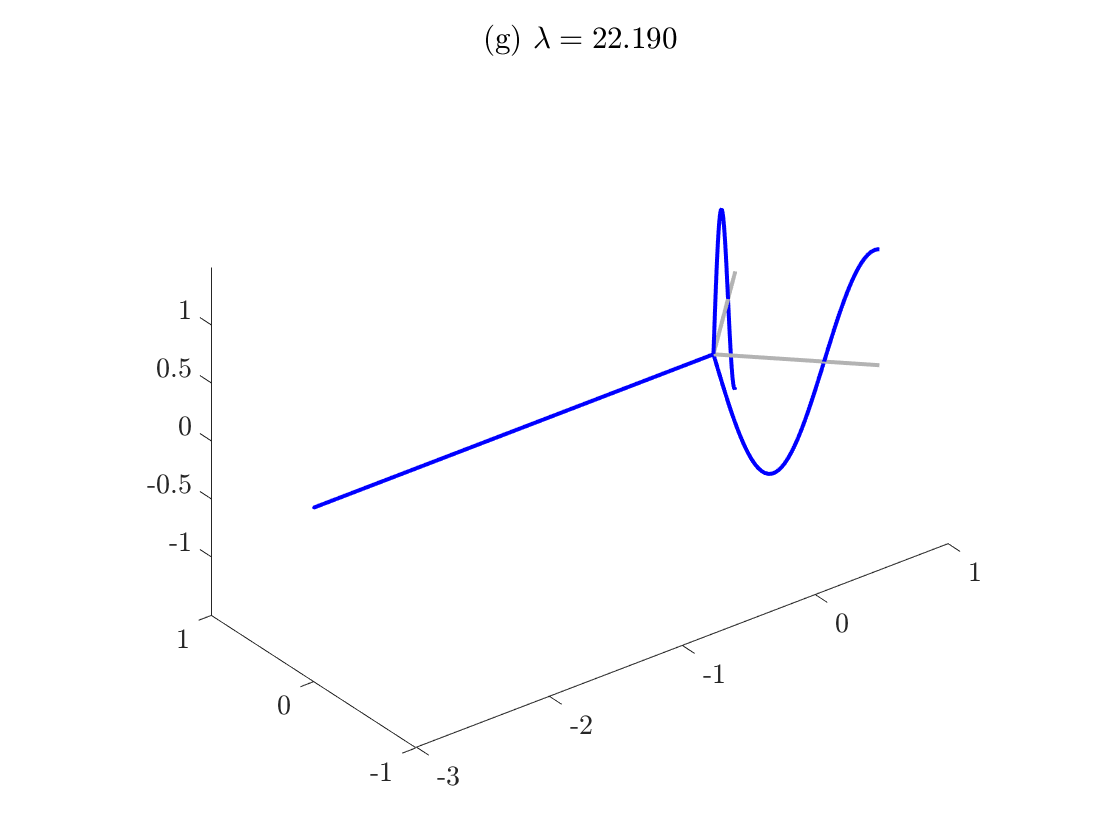

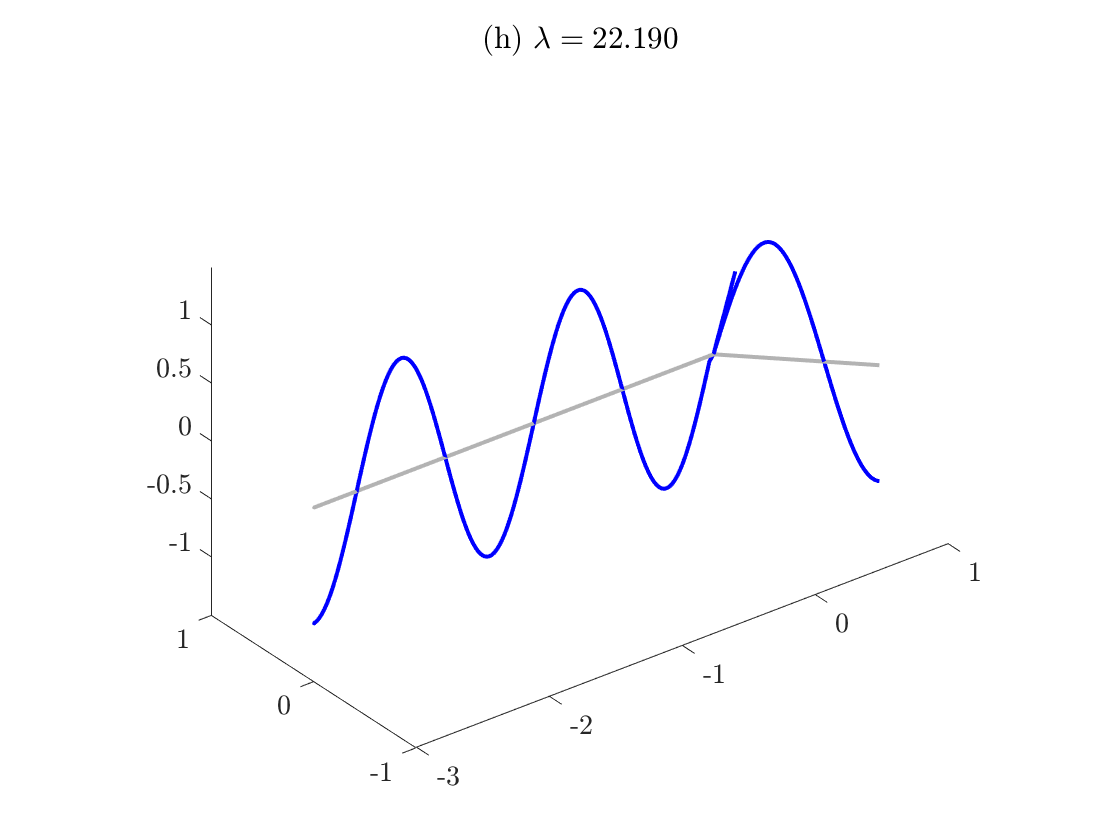

if ~isempty(doubles)
    for k=1:nToPlot/2
        v=yShapeResolveDoubles(V,doubles(k),nX);
        figure
        Phi.plot(v{1})
        title(sprintf('(%s) $\\lambda = %0.3f$', letter(nToPlot+2*k-1), lambda(doubles(k))));
        figure
        Phi.plot(v{2})
        title(sprintf('(%s) $\\lambda = %0.3f$', letter(nToPlot+2*k), lambda(doubles(k))));
    end
end